# Exercise 2: Count the number of mangoes using YOLOv4

## Exercise 2: Part 1

Run the different mango images through an out-of-the-box YOLOv4 detector trained on the COCO dataset. 

addpath("data");
inputImage = "data/mango4.jpg"

inputImage = "data/mango4.jpg"

Read in our image and make it the right size

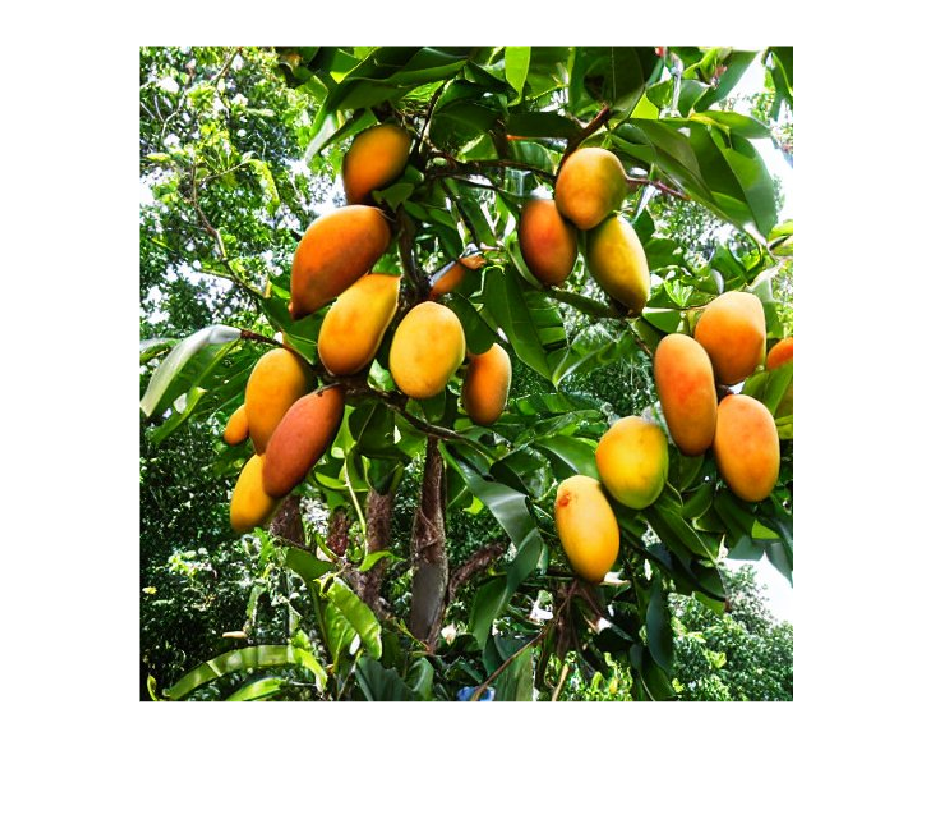

I = imread(inputImage);
imshow(I)

I = imresize(I, [224 224]);

Pass our image through the YOLOv4 network

[outImg, ~] = vanilla_yolov4_detection_mex(I,0.05);

Unrecognized function or variable 'vanilla_yolov4_detection_mex'.

Display our final output image

imshow(outImg)

## Exercise 2: Part 2

Put the mango images through the transfer learned YOLOv4

inputImage = "data/mango4.jpg"

Read in our image and make it the right size

I = imread(inputImage);
I = imresize(I, [224 224]);

Detect the mangoes using the transfer learned YOLOv4

[outImg, bboxes] = yolov4_detection_mex(I,0.05);
imshow(outImg)

## Exercise 2: Part 3

## Count the number of mangoes by counting the number of bounding boxes

% Write your code here
% count the number of bounding boxes stored in the variable "bboxes"

